# Fuzzy Logic Control Systems

## Introduction:

Computers are well known to work off of 1s and 0s called bits and using this concrete system, many complex programs and algorithms can be made. It is not without its own limitations however, as if one were to come across a situation where neither of the two extremes fits what describes their variable, the system becomes unviable. What fuzzy logic does is allow for values between those two extremes and access to a whole range of outputs instead of only 1 and 0.

## Theory:

How does logic read in between true and false you may ask? Well it does this through analyzing a set of if-then statements, which are the set of rules that map the provided inputs to the outputs. For example say you wanted to know how much to tip someone at a resteraunt based on the quality of the service and food. Using fuzzy logic you could get an if-then statement like: "If the food is good and the service is good, then the tip will be high". But just if-then statements are not enough, after all saying "the food is good" is not enough to describe to the computer how delicious the food is. So instead we need to give it a scale of what makes a food good, say like a scale from 1 to 10. For each statement type, "the food is good", "the food is ok", and "the food is bad", each would need a distribution to describe it which are described in the code as input triangles. When applying a value from the x scale to the triangle, from 1-10, it will output the y value porportion of between 0 and 1 based on where scale peaks, usally at 1, and where it increases or decreases. By describing the quality of the service and the meal on the 1-10 scale and putting them into the if-then statements, this gives us an output triangle describing the portion of tip should be given from each of those if-then statements. The output triangles are then layered on top of each other on one graph, and using their combined shape, we find the centroid in which the x value would give you the tip you would give.

## Psuedo-Code:

%Input values

%Setup input and output triangles based on questions and answers (last variable represents the number of input/output triangles):

Inputs for input triangles: inTriangleStartVal, inTriangleMidVal, inTriangleEndVal, inTriangleMaxVal, inTriangleLenOfMaxVal, iN

Inputs for output triangles: outTriangleStartVal, outTriangleMidVal, outTriangleEndVal, outTriangleMaxVal, outTriangleLenOfMaxVal, oN

for (i = 1 to iN):

    inputTriangles := createTriangle(inTriangleStartVal(i), inTriangleMidVal(i), inTriangleEndVal(i), inTriangleMaxVal(i), inTriangleLenOfMaxVal(i))

end for

for (i = 1 to oN):

    outputTriangles := createTriangle(outTriangleStartVal(i), outTriangleMidVal(i), outTriangleEndVal(i), outTriangleMaxVal(i), outTriangleLenOfMaxVal(i))

end for

%Math

other Inputs: valuesOfInterest, ifThenChoices

for (i = 1 to iN):

    portionsOfInterest := yValOf(valuesOfInterest(i), inputTriangles(i))                            % finds y-values of triangles based on input x-values

    outputPortionsOfInterest := crispOf(ifThenChoices(i), portionsOfInterest(i))              % puts the inputs through if-then statements

end for

for (i = 1 to oN): 

    outputCutTriangles := cutTriangle(outputPortionsOfInterest(i), outputTriangles(i))     % takes output portion and applies them to the output triangles

end for

unionizedTriangles := unifyShape(outputCutTriangles)                                        % unionizes the outputed portion of the triangles

[x-bar, y-bar] := centroid(unionizedTriangles)                                                        % finds the centeroid of the unionized figure

display(x-bar)                                                                                                         % The final output displaying the clear output (if for tipping it would show the tip percent)

## Algorithmic Time Complexity:

Whenever a new triangle is instantiated, the triangle class complexity is incurred. Most involved in the triangle class are assignment operations giving a O(1) complexity, but when triangleRange, xrange, and ArrayOfInterest, is solved for, the complexity shoots up to O(k), where k is the total number of points in the array of either triangleRange, or xrange and can be represented as:


$$k=2 \cdot \frac{maxVal}{incriment}+lenOfMax$$


This formula shows the calculation incrimenting up and down and then taking in account the length at the top. Going to the main window, the complexity once again sticks around O(1) for all the assignment operators, but then multiple individual for loops are incurred for triangle assignment. For all 'i' input triangles and 'o' output triangles, there is also the an additional k complexity from triangle class which leads to a total complexity, including the for loops up until polyshapes, so far of:


$$O=(i+o) \cdot k + 2i + 2o$$


The polyshapes intialization are each O(p) where p represents the number of points on an outputed triangle, and combined with the for loop, this section gives a complexity of O(op). Then there is the union function that combines the shapes together which, as my best guess, has a complexity of $p \cdot log(p)$ (see Segment Intersection Algorithm link). My 'estimated' guess stems from the way I imagine this function runs which is by taking the each point and checking edge intersection which then rearranges them, and finally reconstructs it. I imagine that this is something that does not stop at just each point and can occur multiple times on the same point which makes me think this is a recursive algorithm that leads to a nlogn format. The final complexity is the one involving solving for the centroid where since it is likely solved by knowing the verticies of the shape, the worst case complexity would be O(op) where o*p is the max number of verticies that could be on the combined polygon. With that the final time complexity of this algoritm is:

 
$$O=(i+o) \cdot k + 2i + 2o + p + p \cdot log (p) + op = O(nlogn)$$


## Applications:

When inputs in a program are not clearly true or false due to a qualtitative nature or in a quantitative range, fuzzy logic is widely used when this is the case. One example is an air conditioner, as it does not rely on the two extremes of monitering whether it is hot or it is cold and instead manages between them to decide what fan speed to move at based on the temperature range, humidity, etc. Another example are brightness varying displays where they detect how much light is in an area and decide how bright the screen needs to be. Washing machines use system as well when washing clothes since they have take in account laundry weight and dirt accumulation to decide how much detergant to use or when to replenish the water.

## Conclusion:

In conclusion, fuzzy logic is a powerful algorithm for the use of programs that require inputs that are qualitative or have quantative range of semi truths. Its use cases are found to be quite sprawling and relatable to most people making this system rather robust. In the cases where it is needed, it will work well for considering a large number of factors that are not always just true or false. On the other hand if it is not needed, I think I will stick to nested if-then statements next time.

## References:

[https://www.l-tron.com/fuzzy-logic-in-real-life/](https://www.l-tron.com/fuzzy-logic-in-real-life/) 

[https://www.mathworks.com/help/fuzzy/foundations-of-fuzzy-logic.html](https://www.mathworks.com/help/fuzzy/foundations-of-fuzzy-logic.html) 

[https://www.mathworks.com/help/fuzzy/what-is-fuzzy-logic.html](https://www.mathworks.com/help/fuzzy/what-is-fuzzy-logic.html)

[https://www.mathworks.com/help/fuzzy/fuzzy-inference-process.html](https://www.mathworks.com/help/fuzzy/fuzzy-inference-process.html) 

[https://www.eecs.yorku.ca/~aaw/legacy/TristanCarvelho/SegmentIntersectionAlgorithm.html](https://www.eecs.yorku.ca/~aaw/legacy/TristanCarvelho/SegmentIntersectionAlgorithm.html#:~:text=The%20Bentley%2DOttmann%20General%20Line,(n%5E2)%20time.)

## How to use

You can directly manipulate the values for the input triangles and output triangles to how you like and it will display in the graphs shown below. You can also change any of the general details of the triangles including the values of interest, the if-then causes, and even the color (you have 3 choices). Note: changing the triangle input and output properties only run up until the secound graph and the general properties changing run the entire program.

Key:

length of max - how many points long the max porportion is

Max value - the highest porportion

Mid value - the x value the triangle centers at

Start value - the x value the triangle starts at

Ending value - the x value the triangle ends at (roughly)

Value of Interest - the x value to decide the porportion to be used for fuzzification

If-Then Statement - Each input triangles' porportions of interest are inputted in order (so if for an output triangle you put "Or" "And", it will compute from left to right as Triangle 1 or Triangle 2 and Triangle 3)

Color - I only thought of 3 colors, dill with it.

## Triangle Intialization

clc; clear;
warning('off');


Input Triangle Properties


inlenOfMax = [1, 1, 1];               %number of values that are max (set to 1 for triangle)
inmaxVal = [1, 1, 1];                 %max value (between 0 and 1)

inmidXVal = [4, 5, 6];               %middle x value that triangle centers at
instartXVal = [2, 3, 5];             %Start x value that triangle starts at
infinalXVal = [6, 7, 8];           %final x value that triangle ends at


Output Triangle Properties


outlenOfMax = [1, 1, 1];               %number of values that are max (set to 1 for triangle)
outmaxVal = [1, 1, 1];                 %max value (between 0 and 1)

outmidXVal = [5, 4, 15];               %middle x value that triangle centers at
outstartXVal = [0, 3, 9];             %Start x value that triangle starts at
outfinalXVal = [10, 12, 18];           %final x value that triangle ends at


General Triangle Properties


valuesOfInterest = [8, 6, 6];       %Interested value in particular triangle

fuzzyChoices = {["or", "or"], ... %If then statements to determine crisp output (always need to be one less than values of interest
    ["or", "or"], ... 
    ["or", "or"]};       

colors = ["r", "b", "g"];        %colors of each triangle

inputRange = [min(instartXVal),max(infinalXVal)];                %Range of xVals for inputTriangles
outputRange = [min(outstartXVal),max(outfinalXVal)];               %Range of xVals for outputTriangles

numInputTriangles = 3;              %number of input triangles
numOutputTriangles = 3;             %number of output triangles

inputTriangles = cell(1, numInputTriangles);
outputTriangles = cell(1, numOutputTriangles);

for i = 1:numInputTriangles
    inputTriangles{i} = ...
        Triangle('lenOfMax', inlenOfMax(i), 'maxVal', inmaxVal(i), 'midXVal', inmidXVal(i), ...
        'startXVal', instartXVal(i), 'finalXVal', infinalXVal(i), 'color', colors(i));
end

% Fuzzy Logic Put into Effect

% gets the y-values for input triangles from the x-valuesOfInterest
for i = 1:numInputTriangles
    portionsOfInterest = fuzzification(valuesOfInterest, inputTriangles{i});
end

crispOutputs = ones(1, numOutputTriangles);
% Takes y-values and runs them through the if then statements (see fuzzyChoices)
for i = 1:numOutputTriangles
    crispOutputs(i) = defuzzification(portionsOfInterest, fuzzyChoices{i});
end

% Assgins the values for the outputTriangles
for i = 1:numOutputTriangles
    outputTriangles{i} = ...
        Triangle('lenOfMax', outlenOfMax(i), 'maxVal', outmaxVal(i), 'midXVal', outmidXVal(i), ...
        'startXVal', outstartXVal(i), 'finalXVal', outfinalXVal(i), 'color', colors(i), 'portionOfInterest', crispOutputs(i));
end


Setup Graph

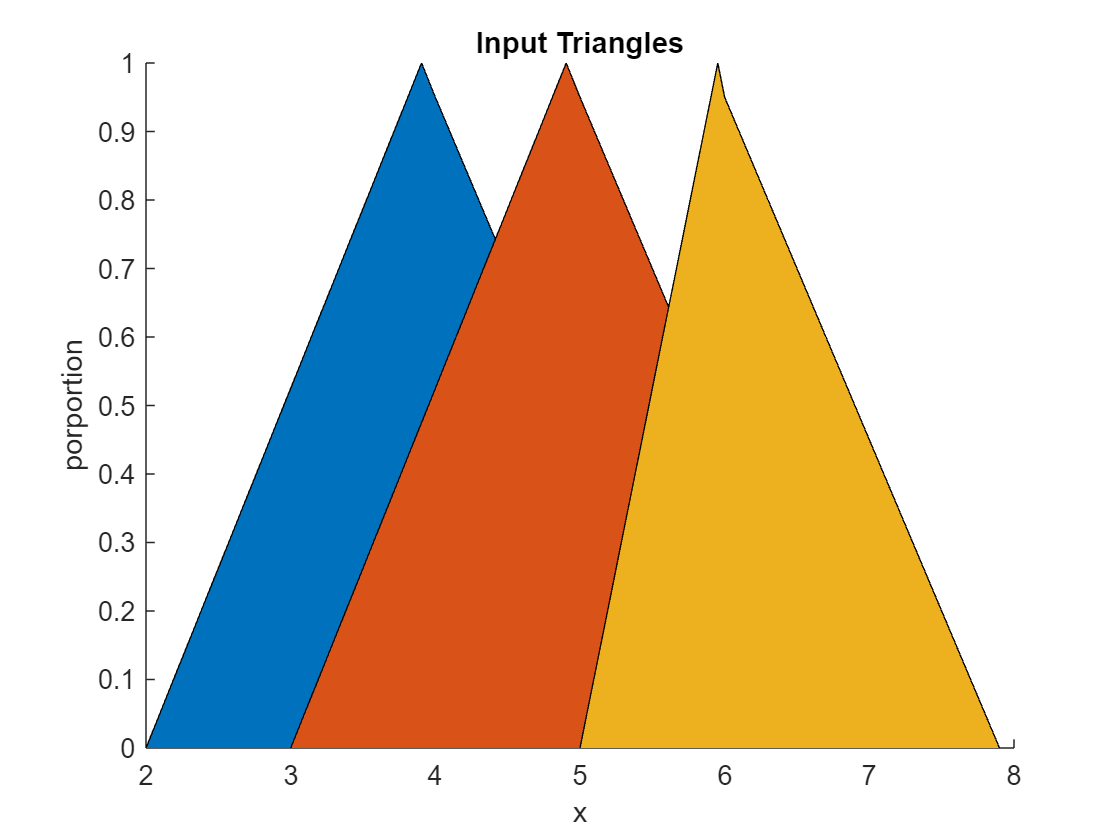

figure("Name", "InputTriangles");
tiledlayout(1,2)

hold on
for i = 1:numInputTriangles
    area(inputTriangles{i}.xrange, inputTriangles{i}.triangleRange);
end 

title("Input Triangles")
xlabel("x")
ylabel("porportion")

ylim([0,1]);
xlim(inputRange);

nexttile

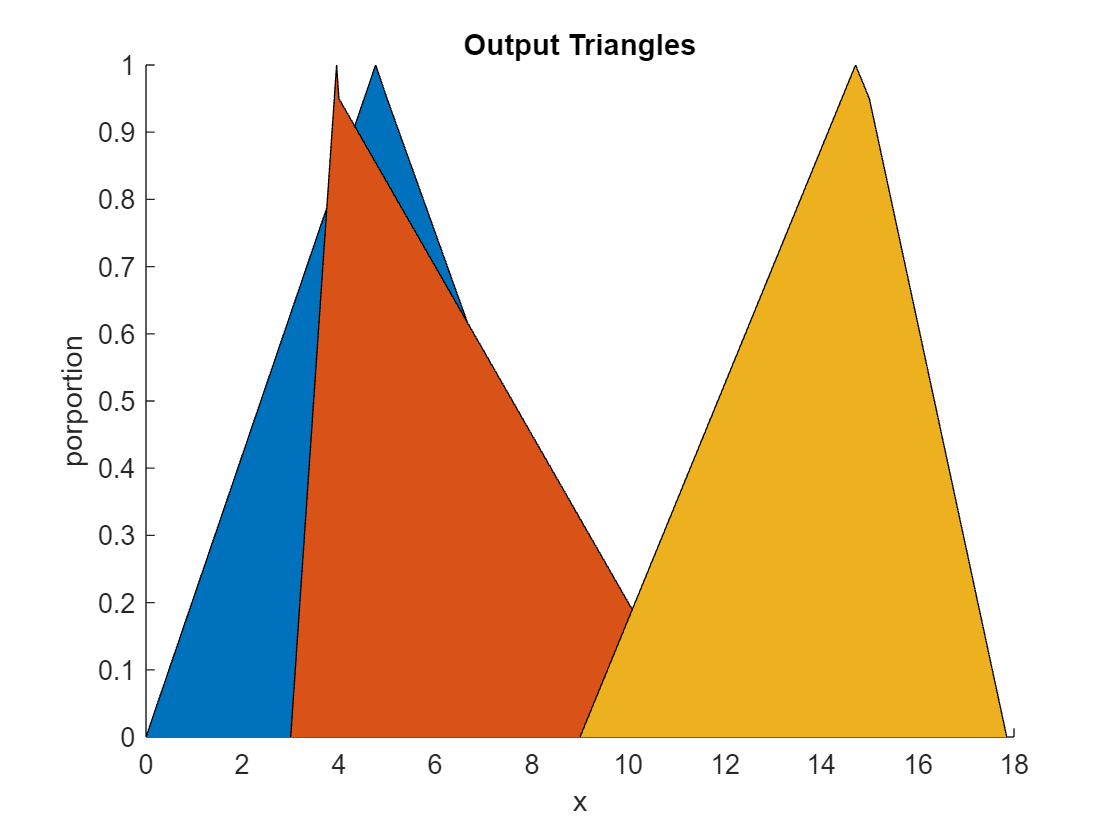


hold on
for i = 1:numOutputTriangles
    area(outputTriangles{i}.xrange, outputTriangles{i}.triangleRange);
end 

title("Output Triangles")
xlabel("x")
ylabel("porportion")

ylim([0,1]);
xlim(outputRange);
hold off;

% Fuzzy Logic Put into Effect

% gets the y-values for input triangles from the x-valuesOfInterest
for i = 1:numInputTriangles
    portionsOfInterest = fuzzification(valuesOfInterest, inputTriangles{i});
end

crispOutputs = ones(1, numOutputTriangles);
% Takes y-values and runs them through the if then statements (see fuzzyChoices)
for i = 1:numOutputTriangles
    crispOutputs(i) = defuzzification(portionsOfInterest, fuzzyChoices{i});
end

% Assgins the values for the outputTriangles
for i = 1:numOutputTriangles
    outputTriangles{i} = ...
        Triangle('lenOfMax', outlenOfMax(i), 'maxVal', outmaxVal(i), 'midXVal', outmidXVal(i), ...
        'startXVal', outstartXVal(i), 'finalXVal', outfinalXVal(i), 'color', colors(i), 'portionOfInterest', crispOutputs(i));
end

trapCentroids = ones(2, numOutputTriangles);
polyTriangles = cell(1, numOutputTriangles);

for i = 1:numOutputTriangles
    polyTriangles{i} = polyshape(outputTriangles{i}.xrange, outputTriangles{i}.arrayOfInterest);
    %[trapCentroids(1,i), trapCentroids(2,i)] = centroid(polyTriangles(i));
end
polyUninon = polyTriangles{1};

for i = 1:numOutputTriangles
    polyUninon = union(polyUninon, polyTriangles{i});
end

[xbar,ybar] = centroid(polyUninon);


Output Triangle Plot

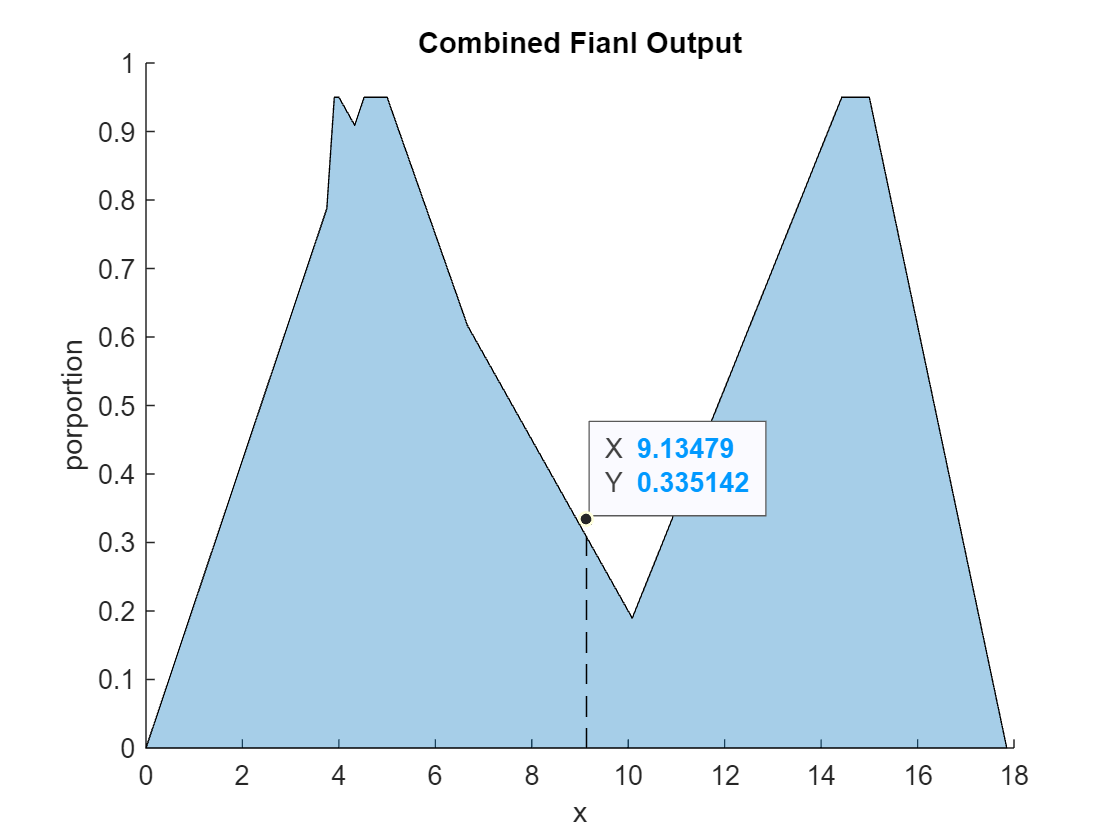


figure("Name", "Combined Fianl Output");
hold on;
plot(polyUninon);

ylim([0,1]);
xlim(outputRange);

centroid = plot(xbar, ybar, 'black *');
datatip(centroid);
plot([xbar xbar], [0 ybar], 'k--');

title("Combined Fianl Output")
xlabel("x")
ylabel("porportion")

hold off

Functions

function portionsOfInterest = fuzzification(valsOfInterst, argTriangle)
   
    portionsOfInterest = ones(1, length(valsOfInterst));
    
    %finds the closest index to the value of interest
   for i = 1:(length(valsOfInterst))
    [~, idx] = min(abs(argTriangle.xrange-valsOfInterst(i)));
    portionsOfInterest(i) = argTriangle.triangleRange(idx);
   end

end

function crisp = defuzzification(valuesOfInterest, fuzzyChoices)
    
    crisp = valuesOfInterest(1); %does not take in account if first value is not used

     try          %if only 1 valueOfInterest, return first value
        for i = 1:length(fuzzyChoices)
       
            if fuzzyChoices(i) == "and"         %if A and B then take the min of them
                crisp = min(crisp, valuesOfInterest(i+1));
            elseif fuzzyChoices(i) == "or"      %if A or B then take the max of them
                crisp = max(crisp, valuesOfInterest(i+1));
            else                                %if neither, crisp is the value
                %crisp = crisp;
            end
        end
     catch
        return
     end
end